# q3a

clc;
clear;
close all;

we = 2*pi*60

we = 376.9911

Vs = 480

Vs = 480

Ls = 28e-3

Ls = 0.0280

PR = 23e3

PR = 23000

Ps = PR

Ps = 23000

p = 4

p = 4

weR = 2*pi*60

weR = 376.9911

Xs = Ls*we

Xs = 10.5558


Te = Ps*p/weR/2

Te = 122.0188

Ps = 23e3

Ps = 23000

Ei = 310

Ei = 310

sindel = Te*(-2/3/p)*weR*Xs/Vs/Ei

sindel = -0.5439

del = asin(sindel)

del = -0.5750

del_degree = del*180/pi

del_degree = -32.9473


Vs_ph = Vs

Vs_ph = 480

Ei_ph = Ei*exp(j*del)

Ei_ph = 2.6014e+02 - 1.6860e+02i

abs(Ei_ph)

ans = 310

jXsIs_ph = Vs_ph-Ei_ph

jXsIs_ph = 2.1986e+02 + 1.6860e+02i

Is_ph = jXsIs_ph/j/Xs

Is_ph = 15.9722 - 20.8282i

abs(Is_ph)

ans = 26.2474

angle(Is_ph)

ans = -0.9166

thetas=angle(Is_ph)

thetas = -0.9166

thetas_degree = thetas

thetas_degree = -0.9166

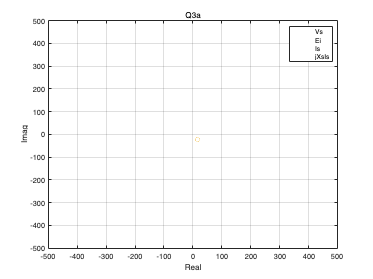


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q3a')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
plot(real(jXsIs_ph),imag(jXsIs_ph),"o",'DisplayName','jXsIs')
xlim([-500 500])
ylim([-500 500])
legend
grid on;

## Q3b

Is_var = abs(Is_ph)

Is_var = 26.2474

Is_ph = Is_var

Is_ph = 26.2474

Ei_ph = Vs_ph - j*Xs*Is_ph

Ei_ph = 4.8000e+02 - 2.7706e+02i

abs(Ei_ph)

ans = 554.2225

angle(Ei_ph)

ans = -0.5235

Po = 3*(Vs_ph*Is_ph)

Po = 3.7796e+04

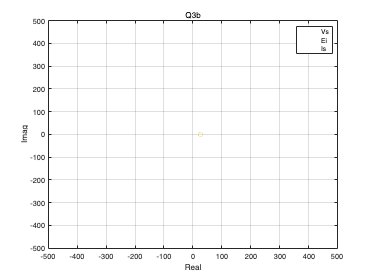


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q3b')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
xlim([-500 500])
ylim([-500 500])
legend
grid on;

## Q3C

PB = 23e3

PB = 23000

VB = 480/sqrt(3)

VB = 277.1281

wB = 2*pi*60

wB = 376.9911

wmB = 2*pi*30

wmB = 188.4956

TB = PB/wmB

TB = 122.0188

IB = PB/3/VB

IB = 27.6647

ZB = VB/IB

ZB = 10.0174

rs = 180e-3

rs = 0.1800


rs_pu = rs/ZB

rs_pu = 0.0180

Xs_pu = Xs/ZB

Xs_pu = 1.0537

## Q4a

clc;
clear;
Xs = 0.6

Xs = 0.6000

we = 1.0

we = 1

rs = 0

rs = 0

Ei = 1.15

Ei = 1.1500

gamma = 0.25

gamma = 0.2500


syms Is_var
Ei_ph = Ei

Ei_ph = 1.1500

eqn=Is_var*cos(gamma)*(Ei-Is_var*Xs*sin(gamma))-Is_var^2*Xs*cos(gamma)*sin(gamma)-1/3

$$eqn = -\frac{8727187242741409\,{\mathrm{Is}}_{\mathrm{var}}\,\left(\frac{26741001089007717\,{\mathrm{Is}}_{\mathrm{var}}}{180143985094819840}-\frac{23}{20}\right)}{9007199254740992}-\frac{233373723562122273118346636453253\,{{\mathrm{Is}}_{\mathrm{var}}}^{2}}{1622592768292133633915780102881280}-\frac{1}{3}$$

solve(eqn)

$$ans = \left(\begin{array}{c} \frac{51791395714760704}{26741001089007717}-\frac{2251799813685248\,\sqrt{27844050112880527391861372697653489}}{233373723562122273118346636453253}\\ \frac{2251799813685248\,\sqrt{27844050112880527391861372697653489}}{233373723562122273118346636453253}+\frac{51791395714760704}{26741001089007717} \end{array}\right)$$


is_set = double(solve(eqn))

is_set =     0.3267
    3.5468


Is = is_set(1,1)

Is = 0.3267


Is_ph = Is*exp(j*gamma)

Is_ph = 0.3166 + 0.0808i

Vs_ph = Ei-Is*Xs*sin(gamma)+j*Is*Xs*cos(gamma)

Vs_ph = 1.1015 + 0.1899i


Pin = real(Is_ph*Vs_ph)

Pin = 0.3333

S = abs(Is_ph)*abs(Vs_ph)

S = 0.3652

pf = Pin/S

pf = 0.9128


Vs=abs(Vs_ph)

Vs = 1.1178

angle(Is_ph)

ans = 0.2500

angle(Vs_ph)

ans = 0.1708

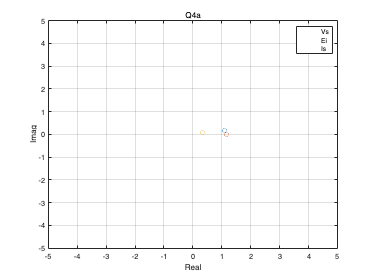


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q4a')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
xlim([-5 5])
ylim([-5 5])
legend
grid on;


Is = is_set(2,1)

Is = 3.5468


Is_ph = Is*exp(j*gamma)

Is_ph = 3.4366 + 0.8775i

Vs_ph = Ei-Is*Xs*sin(gamma)+j*Is*Xs*cos(gamma)

Vs_ph = 0.6235 + 2.0619i


Vs=abs(Vs_ph)

Vs = 2.1542

angle(Is_ph)

ans = 0.2500

angle(Vs_ph)

ans = 1.2772


thetas = angle(Vs_ph)-angle(Is_ph)

thetas = 1.0272

cos(thetas)

ans = 0.5173


Pin = real(Is_ph*Vs_ph)

Pin = 0.3333

S = abs(Is_ph)*abs(Vs_ph)

S = 7.6405

pf = Pin/S

pf = 0.0436

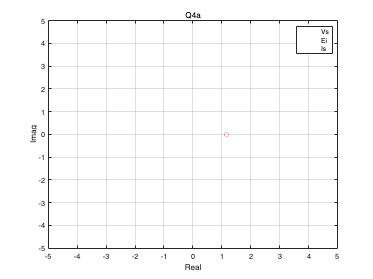


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q4a')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
xlim([-5 5])
ylim([-5 5])
legend
grid on;

## Q4b

Is = is_set(1,1)

Is = 0.3267

gamma = -pi:0.0001:pi

gamma =    -3.1416   -3.1415   -3.1414   -3.1413   -3.1412   -3.1411   -3.1410   -3.1409   -3.1408   -3.1407   -3.1406   -3.1405   -3.1404   -3.1403   -3.1402   -3.1401   -3.1400   -3.1399   -3.1398   -3.1397   -3.1396   -3.1395   -3.1394   -3.1393   -3.1392   -3.1391   -3.1390   -3.1389   -3.1388   -3.1387   -3.1386   -3.1385   -3.1384   -3.1383   -3.1382   -3.1381   -3.1380   -3.1379   -3.1378   -3.1377   -3.1376   -3.1375   -3.1374   -3.1373   -3.1372   -3.1371   -3.1370   -3.1369   -3.1368   -3.1367


Power = Is*cos(gamma).*(1.15-Is*sin(gamma)*Xs)-Is*sin(gamma)*Is.*cos(gamma)*Xs

Power =    -0.3757   -0.3757   -0.3757   -0.3758   -0.3758   -0.3758   -0.3758   -0.3758   -0.3758   -0.3758   -0.3758   -0.3759   -0.3759   -0.3759   -0.3759   -0.3759   -0.3759   -0.3759   -0.3759   -0.3760   -0.3760   -0.3760   -0.3760   -0.3760   -0.3760   -0.3760   -0.3760   -0.3761   -0.3761   -0.3761   -0.3761   -0.3761   -0.3761   -0.3761   -0.3762   -0.3762   -0.3762   -0.3762   -0.3762   -0.3762   -0.3762   -0.3762   -0.3763   -0.3763   -0.3763   -0.3763   -0.3763   -0.3763   -0.3763   -0.3763


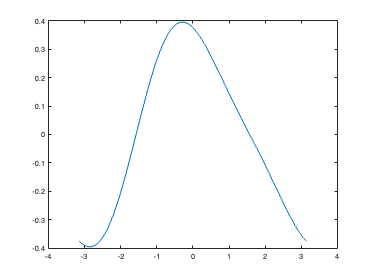


figure
plot(gamma,Power)


[Max_power max_i] = max(Power)

Max_power = 0.3951

max_i = 28523

gamma(max_i)

ans = -0.2894


max_gamma = gamma(max_i)

max_gamma = -0.2894


Is_ph = Is*exp(j*max_gamma)

Is_ph = 0.3131 - 0.0932i

Vs_ph = Ei-Is*Xs*sin(max_gamma)+j*Is*Xs*cos(max_gamma)

Vs_ph = 1.2059 + 0.1879i

abs(Vs_ph)

ans = 1.2205

angle(Vs_ph)

ans = 0.1545

S = abs(Is_ph)*abs(Vs_ph)

S = 0.3987

pf = Max_power/S

pf = 0.9909

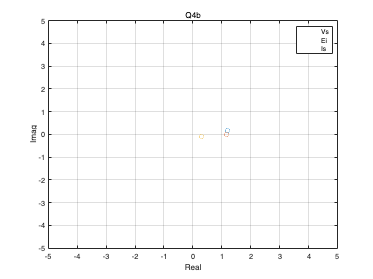


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q4b')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
xlim([-5 5])
ylim([-5 5])
legend
grid on;


Is = is_set(2,1)

Is = 3.5468

gamma = -pi:0.0001:pi

gamma =    -3.1416   -3.1415   -3.1414   -3.1413   -3.1412   -3.1411   -3.1410   -3.1409   -3.1408   -3.1407   -3.1406   -3.1405   -3.1404   -3.1403   -3.1402   -3.1401   -3.1400   -3.1399   -3.1398   -3.1397   -3.1396   -3.1395   -3.1394   -3.1393   -3.1392   -3.1391   -3.1390   -3.1389   -3.1388   -3.1387   -3.1386   -3.1385   -3.1384   -3.1383   -3.1382   -3.1381   -3.1380   -3.1379   -3.1378   -3.1377   -3.1376   -3.1375   -3.1374   -3.1373   -3.1372   -3.1371   -3.1370   -3.1369   -3.1368   -3.1367


Power = Is*cos(gamma).*(1.15-Is*sin(gamma)*Xs)-Is*sin(gamma)*Is.*cos(gamma)*Xs

Power =    -4.0789   -4.0804   -4.0819   -4.0834   -4.0849   -4.0864   -4.0879   -4.0894   -4.0909   -4.0925   -4.0940   -4.0955   -4.0970   -4.0985   -4.1000   -4.1015   -4.1030   -4.1045   -4.1060   -4.1075   -4.1091   -4.1106   -4.1121   -4.1136   -4.1151   -4.1166   -4.1181   -4.1196   -4.1211   -4.1226   -4.1241   -4.1257   -4.1272   -4.1287   -4.1302   -4.1317   -4.1332   -4.1347   -4.1362   -4.1377   -4.1392   -4.1407   -4.1422   -4.1437   -4.1453   -4.1468   -4.1483   -4.1498   -4.1513   -4.1528


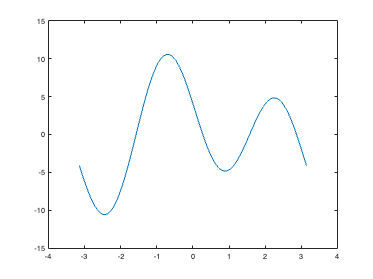


figure
plot(gamma,Power)


[Max_power max_i] = max(Power)

Max_power = 10.5580

max_i = 24436

gamma(max_i)

ans = -0.6981


max_gamma = gamma(max_i)

max_gamma = -0.6981


Is_ph = Is*exp(j*max_gamma)

Is_ph = 2.7171 - 2.2798i

Vs_ph = Ei-Is*Xs*sin(max_gamma)+j*Is*Xs*cos(max_gamma)

Vs_ph = 2.5179 + 1.6303i

abs(Vs_ph)

ans = 2.9996

angle(Vs_ph)

ans = 0.5746

S = abs(Is_ph)*abs(Vs_ph)

S = 10.6390

pf = Max_power/S

pf = 0.9924

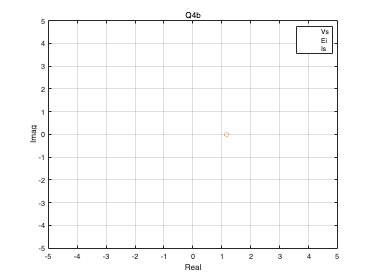


figure
plot(real(Vs_ph),imag(Vs_ph),"o",'DisplayName','Vs')
title('Q4b')
xlabel('Real')
ylabel('Imag')
hold on;
plot(real(Ei_ph),imag(Ei_ph),"o",'DisplayName','Ei')
plot(real(Is_ph),imag(Is_ph),"o",'DisplayName','Is')
xlim([-5 5])
ylim([-5 5])
legend
grid on;